# Sensing System - revD

Changes since previous version:

- removed SIMULINK model integration as it was very finicky

To-Do's:

- significantly simplify the first step of loading samples into the sensing subsystem itself to be more in line with what will happen on the USRP

- Modify the simulator to be able to run off of a JSON configuration instead of having a function for each piece

## Key parts of the Sensing Subystem

### Debugging Capability

For each debuger array, the format will be as follows:

- 1st column - number of frames computed at that point

- 2nd column - number of chirps computed at that point

- remainder of columns - data taken

## Generate a Spectogram

Steps to generate spectoram:

- reshape into 1us wide windows to sample frequency at (ex: 50 samples per 1us when sampling at 50 Msps)

- reduce the number of samples in the window to the desired size of fft (ex: 32 bits)

- window the sample signal

- perform fft

### Revised Linear Model Computation:

link to resourse used to compute linear model: [https://online.stat.psu.edu/stat462/node/132/](https://online.stat.psu.edu/stat462/node/132/) 

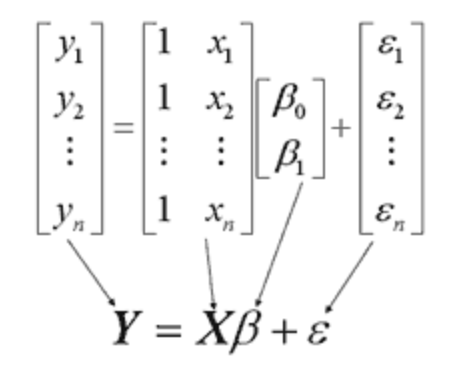

solving for this with out the Epsilon term though


$$\beta = (X^{T}X)^{-1}X^{T}Y$$


## Initializing the Sensing Subsystem in Simulink

clear;
simulator = Simulator_revB();
file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_sensing_system.json";
simulator.load_params_from_JSON(file_path)

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default target, attacker, and victim positions and velocities
simulator.load_target_realistic;
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 1.20 MHz/us
	 Idle Time: 			 1.95 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.49 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 1.54 MSps
	 Ramp End Time: 		 48.05 us
	 Chirp Tx Bandwidth: 		 57.66 MHz
	 Chirp Sampling Bandwidth: 	 49.87 MHz
	 ADC Sampling Period: 		 41.56 us
	 Chirp Cycle Time: 		 50.00 us
	 Chirp Wavelength: 		 3.89 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 16
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 0.80 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 192.37 m
	 Range Resolution 		 3.01 m
	 Max Velocity 			 19.47 m/s
	 Velocity Resolution 		 2.43 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 58.52 MHz
	 Downsampling factor 		 38
	 Sweep time 			 48.05 us
	 Samples per chirp 		 2926.00 





%specify the number of frames to be computed
frames_to_compute = 5;

%initialize the sensing subsystem of the attacker
simulator.Attacker.Subsystem_spectrum_sensing.initialize_spectrum_sensing_parameters(simulator.Victim.FMCW_sampling_rate_Hz * 1e-6);

%initialize the sensing subsystem's debugger
simulator.Attacker.Subsystem_spectrum_sensing.initialize_debugger(1,simulator.Victim,frames_to_compute);


%for use in the simulink model
fft_size = simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.fft_size;
captured_chirps_buffer_size = simulator.Attacker.Subsystem_spectrum_sensing.chirp_tracking.captured_chirps_buffer_size;

%linear model computations in simulink
max_num_clusters = simulator.Attacker.Subsystem_spectrum_sensing.clustering_params.max_num_clusters;
threshold = simulator.Attacker.Subsystem_spectrum_sensing.clustering_params.min_num_points_per_cluster;
% half_fft_size = simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.fft_size/2;

## Rewritten Sensor Subsystem Code

simulator.initialize_sensing_subsystem_support();

desired_SNR = 15;
noise_level = 10^(-1 * desired_SNR /20);


while simulator.Victim.current_frame <= frames_to_compute

    received_signal = simulator.Victim.get_radar_signal();

    noise = noise_level * rand(size(received_signal),"like",1.1 + 1.1i);
    
    %simulate the signal being transmitted
    received_signal = simulator.Victim.transmitter(received_signal + noise);

    %insert code to simulate the free space channel

    %simulate the receiver on the victim side
    received_signal = simulator.Attacker.Subsystem_tracking.receiver(received_signal);

    simulator.Attacker.Subsystem_spectrum_sensing.receive_signal(received_signal.');
%     simulator.Attacker.Subsystem_spectrum_sensing.plot_received_spectogram();
%     received_signal = simulator.generate_sensing_subsystem_received_signal();
end

% %print out the relevant information
% fprintf("Average Frame Duration: %5.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_frame_duration);
% fprintf("Average Chirp Duration: %3.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_chirp_duration);
% fprintf("Average Slope: %1.3f MHz/us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_slope);

% %compare the predicted frame start times with the actual frame start times
% actual_frame_start_times = (2:frames_to_compute).' * simulator.Victim.FramePeriodicity_ms * 1e3 ... 
%                                 + simulator.Victim.IdleTime_us;
% predicted_start_time_errors = simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.captured_frames(1:...
%     simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.num_captured_frames,7) ...
%                                 - actual_frame_start_times;
% 
% clf;
% plot(predicted_start_time_errors);

## Run the Debugger if enabled

% if simulator.Attacker.Subsystem_spectrum_sensing.Debugger.enabled
%     simulator.Attacker.Subsystem_spectrum_sensing.debugger_compute_errors(simulator.Victim);
%     [summary_table] = simulator.Attacker.Subsystem_spectrum_sensing.debugger_summarize_errors();
%     summary_table
% end